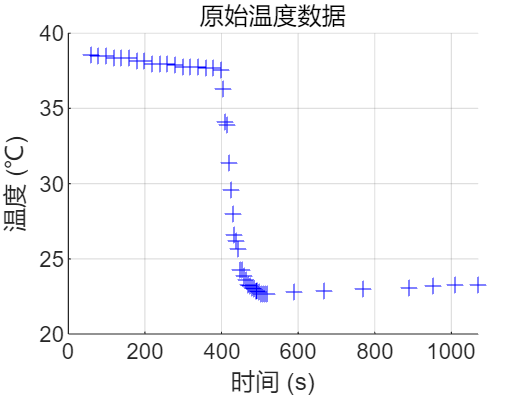

%% 冰融化实验温度曲线拟合
% 作者: Monika
% 描述: 三段式拟合(线性-三次多项式-线性)实现平滑过渡

%% 清理工作区
clear; clc; close all;

%% 导入实验数据(假设数据存储在'data.xlsx'中)
% 数据格式: 第一列为时间(t)，第二列为温度(T)
data = readmatrix('data.xlsx');
t = data(:,1);          % 时间向量(单位:秒)
T = data(:,2);          % 温度向量(单位:℃)

%% 可视化原始数据
figure('Name','原始数据可视化')
% 修改点样式为蓝色十字，添加黑色边缘线
scatter(t, T, 50, 'b+', 'LineWidth', 0.5, 'MarkerEdgeColor', 'b')
xlabel('时间 (s)'); ylabel('温度 (℃)');
title('原始温度数据');
grid on;

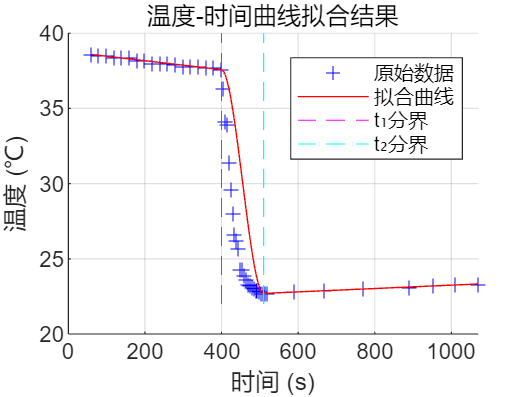



t1 = 400;   % 过渡开始时间
t2 = 510;   % 过渡结束时间

%% 分段线性拟合
% 前段拟合(加热阶段)
mask_pre = t <= t1;
coeff_pre = polyfit(t(mask_pre), T(mask_pre), 1);
a1 = coeff_pre(1);      % 前段斜率
b1 = coeff_pre(2);      % 前段截距

% 后段拟合(融化后阶段)
mask_post = t >= t2;
coeff_post = polyfit(t(mask_post), T(mask_post), 1);
a2 = coeff_post(1);     % 后段斜率
b2 = coeff_post(2);     % 后段截距

%% 构建过渡段三次多项式
% 保证函数值和一阶导数连续性的约束条件
delta_t = t2 - t1;
A = [delta_t^2, delta_t^3;      % 系数矩阵
     2*delta_t, 3*delta_t^2];
B = [(a2*t2 + b2 - (a1*t1 + b1)) - a1*delta_t;  % 常数项
     a2 - a1];
sol = A \ B;                    % 求解线性方程组
p2 = sol(1);                    % 二次项系数
p3 = sol(2);                    % 三次项系数

%% 生成完整拟合曲线
T_fit = zeros(size(t));

% 前段拟合
T_fit(mask_pre) = a1*t(mask_pre) + b1;

% 过渡段拟合
mask_trans = (t > t1) & (t < t2);
t_trans = t(mask_trans) - t1;   % 转换为相对时间
T_fit(mask_trans) = (a1*t1 + b1) + a1*t_trans + p2*t_trans.^2 + p3*t_trans.^3;

% 后段拟合
T_fit(mask_post) = a2*t(mask_post) + b2;

%% 合并可视化
figure('Name','拟合结果')
% 绘制原始数据（蓝色十字）和拟合曲线（红色实线）
scatter(t, T, 40, 'b+', 'LineWidth', 0.5, 'MarkerEdgeColor', 'b')
hold on;
plot(t, T_fit, 'r-', 'LineWidth', 0.6)
plot([t1 t1], ylim, 'm--', [t2 t2], ylim, 'c--', 'LineWidth', 0.5)
xlabel('时间 (s)'); ylabel('温度 (℃)');
legend({'原始数据', '拟合曲线', 't₁分界', 't₂分界'}, 'Location', 'best')
title('温度-时间曲线拟合结果');
grid on;


%% 显示方程和参数
%% text_str = {
%    sprintf('前段方程: T = %.4ft + %.4f', a1, b1), 
%    sprintf('过渡段方程: %.4f + %.4f(t-%d) + %.4f(t-%d)² + %.4f(t-%d)³',...
%            a1*t1 + b1, a1, t1, p2, t1, p3, t1), 
%    sprintf('后段方程: T = %.4ft + %.4f', a2, b2)
%};
% annotation('textbox', [0.15, 0.15, 0.3, 0.2],...
%           'String', text_str,...
%           'FitBoxToText', 'on',...
%           'BackgroundColor', 'w',...
%           'FontName', 'FixedWidth');

%% 拟合质量评估（保持原始输出格式）
residuals = T - T_fit;
SS_res = sum(residuals.^2);      
SS_tot = sum((T - mean(T)).^2); 
R_squared = 1 - SS_res/SS_tot;   

fprintf('拟合质量评估:\n');

拟合质量评估:


fprintf('决定系数 R² = %.4f\n', R_squared);

决定系数 R² = 0.8172


fprintf('最大残差 = %.4f ℃\n', max(abs(residuals)));

最大残差 = 7.3606 ℃


fprintf('平均残差 = %.4f ℃\n', mean(abs(residuals)));

平均残差 = 1.6569 ℃



%% 导出拟合参数（保持原结构体格式）
fit_params = struct(...
    't1', t1, ...
    't2', t2, ...
    'a1', a1, ...
    'b1', b1, ...
    'a2', a2, ...
    'b2', b2, ...
    'p2', p2, ...
    'p3', p3);

disp('拟合参数已存储在结构体fit_params中');

拟合参数已存储在结构体fit_params中
